# Von Bertalanffy Tutorial

## Introduction

In this Livescript, you will be shown how von Bertalanffy works and what the outputs of each sections are.

First, begin by installing all the necessary dependencies. At the time of writing this, the following were used:

**Ubuntu 16.04 LTS**

**Python 2.7**

**NumPy 1.11.1**

**ChemAxon MarvinBeans 16.9.5.0**

**OpenBabel 2.3**

The following commands are entered in a **terminal window (bash or similar shell)**.

## Python 2 

OpenBabel only works with Python 2. Most distributions should already have this installed, but if this is not the case, the following lines will do it: 

sudo add-apt-repository ppa:fkrull/deadsnakes  

sudo apt-get update  

sudo apt-get install python2.7

## NumPy 

NumPy can be installed using the following commands: 

sudo apt-get install python-dev 

sudo apt-get install python-setuptools 

sudo wget http://downloads.sourceforge.net/project/numpy/NumPy/1.11.1/numpy-1.11.1.tar.gz  

sudo tar -xzvf numpy-1.11.1.tar.gz 

sudo cd numpy-1.11.1  

sudo python setup.py build -j 4 install 

## ChemAxon Calculator Plugin 

ChemAxon calculator plugin requires a license. Apply for an academic license at the following link: http://www.chemaxon.com/my-chemaxon/my-academic-license/ 

After your license has been made available, you can download from the “My Licenses” tab on the ChemAxon website. 

Download the license and place it under (replace USER by your actual user account): 

/home/USER/.chemaxon 

Download MarvinBeans for Linux, navigate to the directory where it was saved and make it executable (here, we downloaded version 16.9.5.0 - use the appropriate filename for your version):  

sudo chmod +x marvinbeans-16.9.5.0-linux_with_jre64.sh  

Execute the installer (again, use the same filename as above): 

sudo ./marvinbeans-16.9.5.0-linux_with_jre64.sh 

When asked for an installation directory, make it:  

/opt/ChemAxon/MarvinBeans 

This is important, since this is the path used by COBRA Toolbox. 

Finally, add the installation path to the PATH environment variable: 

PATH=$PATH:/opt/ChemAxon/MarvinBeans/bin 

sudo export PATH

## OpenBabel and Python bindings  

Install the OpenBabel and Python 2 bindings by entering the following: 

sudo apt-get install openbabel  

sudo apt-get install python-openbabel

With all dependencies installed correctly, we configure our environment.

## Add required fields and directories to path

initVonBertalanffy
global CBTDIR
pth=which('initCobraToolbox.m');
CBTDIR = pth(1:end-(length('initCobraToolbox.m')+1));

cd([CBTDIR filesep 'testing' filesep 'testVonBertalanffy'])

## Configure inputs

load iAF1260
if model.S(952,350)==0
    model.S(952,350)=1; % One reaction needing mass balancing in iAF1260
end
model.metCharges(strcmp('asntrna[c]',model.mets))=0; % One reaction needing charge balancing

molfileDir = 'iAF1260Molfiles'; % Directory containing molfiles

cid = []; % KEGG Compound identifiers. Not required since molfile directory is specified.

T = 310.15; % Temperature in Kelvin
cellCompartments = ['c'; 'e'; 'p']; % Cell compartment identifiers
ph = [7.7; 7.7; 7.7]; % Compartment specific pH
is = [0.25; 0.25; 0.25]; % Compartment specific ionic strength in mol/L
chi = [0; 90; 90]; % Compartment specific electrical potential relative to cytosol in mV

xmin = 1e-5*ones(size(model.mets)); % Lower bounds on metabolite concentrations in mol/L
xmax = 0.02*ones(size(model.mets)); % Upper bounds on metabolite concentrations in mol/L

confidenceLevel = 0.95; % Confidence level for estimated standard transformed reaction Gibbs energies. Used to quantitatively assign reaction directionality.

## Call setupThermoModel

modelT = setupThermoModel(model,molfileDir,cid,T,cellCompartments,ph,is,chi,xmin,xmax,confidenceLevel,0);

Error using setupThermoModel
Too many input arguments.


save('iAF1260Thermo_test.mat', 'modelT', '-v7');

## Compare test results to expected results

old = load('iAF1260Thermo.mat');
new = load('iAF1260Thermo_test.mat');


Check for differences in estimated standard transformed Gibbs energies of formation

fig = figure(1);
subplot(1,3,1);
rmse1 = sqrt(mean( (new.modelT.DfGt0 - old.modelT.DfGt0).^2 ));
fprintf('RMSE difference between the old and new DfGt0: %g\n', rmse1);

RMSE difference between the old and new DfGt0: 2.20266


cdfplot(abs((new.modelT.DfGt0 - old.modelT.DfGt0)));
xlabel('|D_f G^{\prime\circ}(new) - D_f G^{\prime\circ}(old)|','FontSize',9);
title(['\Delta_f G^{\prime\circ} RMSE = ' sprintf('%g', rmse1)],'FontSize',9);


Check for differences in estimated standard transformed reaction Gibbs energies

subplot(1,3,2);
rmse2 = sqrt(mean( (new.modelT.DrGt0 - old.modelT.DrGt0).^2 ));
fprintf('RMSE difference between the old and new DrGt0: %g\n', rmse2);

RMSE difference between the old and new DrGt0: 1.66416


cdfplot(abs((new.modelT.DrGt0 - old.modelT.DrGt0)));
xlabel('|D_r G^{\prime\circ}(new) - D_r G^{\prime\circ}(old)|','FontSize',9);
title(['\Delta_r G^{\prime\circ} RMSE = ' sprintf('%g', rmse2)],'FontSize',9);


Check for differences in uncertainty levels - indicative of differences in coverage

subplot(1,3,3);
rmse3 = sqrt(mean( (new.modelT.uf - old.modelT.uf).^2 ));
fprintf('RMSE difference between the old and new uf: %g\n', rmse3);

RMSE difference between the old and new uf: 0.0669083


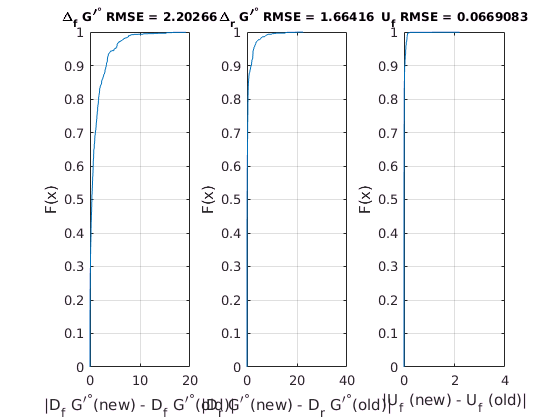

cdfplot(abs((new.modelT.uf - old.modelT.uf)));
xlabel('|U_f (new) - U_f (old)|','FontSize',9);
title(['U_f RMSE = ' sprintf('%g', rmse3)],'FontSize',9);

print(fig, 'iAF1260_compare.eps', '-deps');